**Simulation of a Quarter Car Modeled Using Bond Graph Going Over a Single Bump**

“Everything should be made as simple as possible, but not simpler.” - Einstein

"The modeling cannot be taught and it is done once you have drawn the schematic" - Professor D.L. Margolis

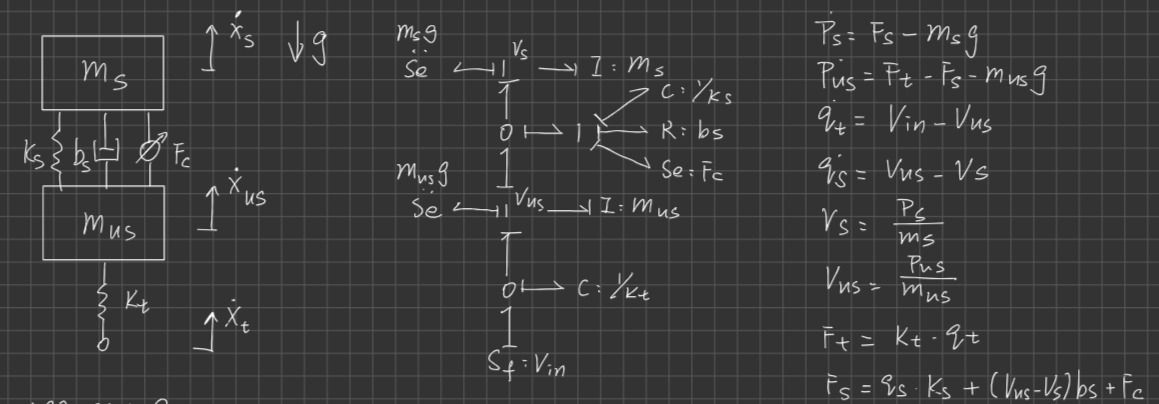

quarter-car model and its bond graph

%% initialization
close all
clear
clc

global mt ms mus ks bs kt A d u g non_lin G

%% quarter car model parameter
mt = 3500/2.2; % total mass [kg]
msmus = 5; % sprung mass unsprung mass ratio
mus = mt/(1+msmus); % unsprung mass [kg]
ms = mt - mus; % sprung mass [kg]
ks = ms*(2*pi*1)^2; % linear suspension spring stiffness
bs = 2*.5*sqrt(ks*ms); % linear suspension damping
kt = mus*(2*pi*8)^2; % linear tire stiffness
g = 9.8; % gravity [m/s^2]

single bump road input

height: 2 * 0.0254 meters

length: .5 meters

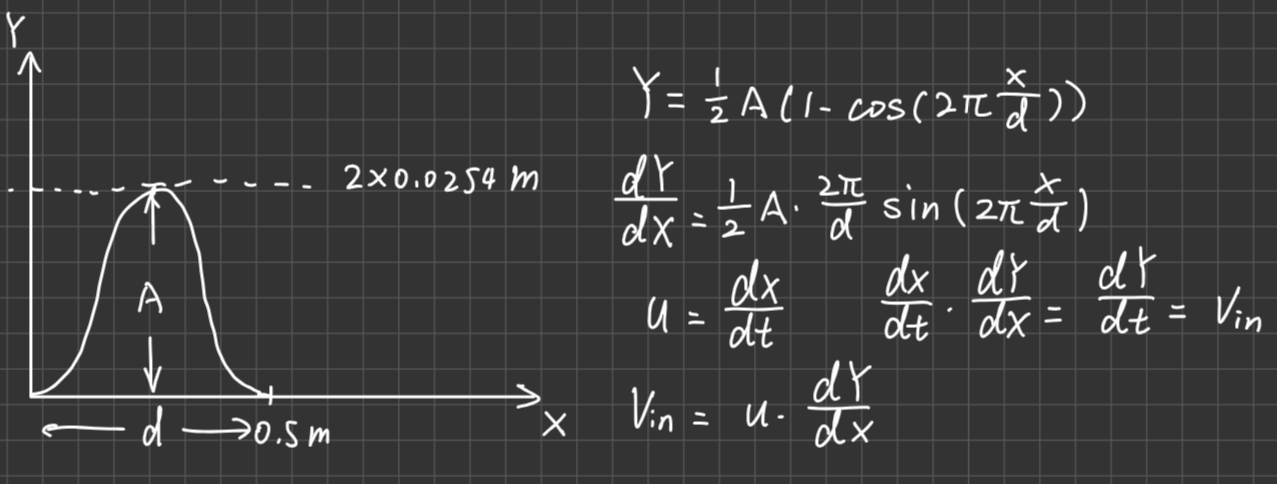

%% road input parameter
A = 2*.0254; % magnitude [m] 2/4/6
% d = 0.5; % bump length [m]
d = 3*.3048;
u = 30*.46; % constant speed [m/s] 20/25/30

Nonlinear Spring (bump stop)

%% nonlineararity activation
non_lin = 1;
% qs_o = 3*ms*g/ks;
% G = ms*g/(qs_o^3);
% G = (ks/(3*(ms*g)^(2/3)))^3;
G = (ks/(3*(ms*g)^(2/3)))^3;

%% initial setup
if non_lin == 1
    initial = [0 0 (ms*g/G)^(1/3) mt*g/kt];
else
    initial = [0 0 1.00*ms*g/ks mt*g/kt]; %initial condition for each state [ps pus qs qt]
end

Simulation time

tspan = 0:.001:1; %simulation time

Calling ODE45

%% calling differential equation solver
[t,s] = ode45(@LabDemoFunc,tspan,initial);
ext = zeros(length(t),7); % create extra observation matrix
ds = zeros(length(t),4); % create states matrix
% ds = [dps; dpus; dqs; dqus];
% ext = [X; Y; Ft; vs; vus; vin; Fss];

for i = 1:length(t)
    [ds(i,:),ext(i,:)] = LabDemoFunc(t(i),s(i,:));
end
% store results

Assign parameter names

%% unpack
ps = s(:,1); pus = s(:,2); qs = s(:,3); qus = s(:,4);
dps = ds(:,1); dpus = ds(:,2); dqs = ds(:,3); dqus = ds(:,4);
X = ext(:,1); Y = ext(:,2); Ft = ext(:,3); vs = ext(:,4); vus = ext(:,5); vin = ext(:,6); Fss = ext(:,7);

Plot the result

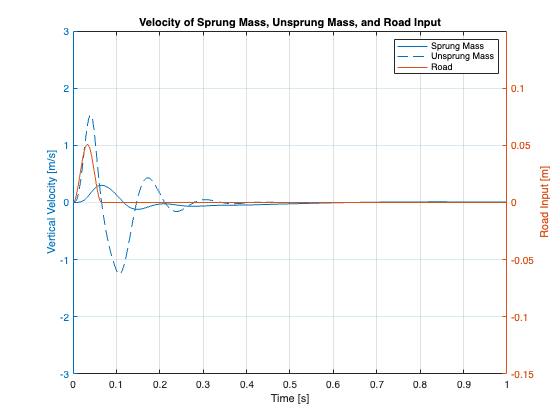

%% plot
figure(1)
yyaxis left
plot(t,vs,t,vus); grid on;
ylabel('Vertical Velocity [m/s]');
ylim([-3 3]);
title('Velocity of Sprung Mass, Unsprung Mass, and Road Input');
yyaxis right
plot(t,Y);
ylabel('Road Input [m]');
ylim([-.15 .15]);
legend('Sprung Mass','Unsprung Mass','Road');
xlabel('Time [s]');

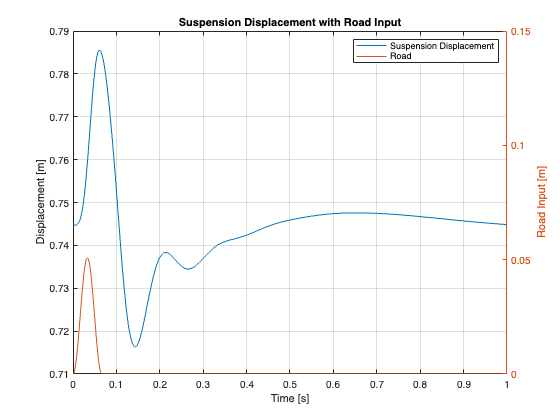


figure(2)
plot(t,qs); grid on;
title('Suspension Displacement with Road Input');
yyaxis left
ylabel('Displacement [m]');
yyaxis right
plot(t,Y);
ylim([0 .15]);
ylabel('Road Input [m]');
xlabel('Time [s]');
legend('Suspension Displacement','Road');

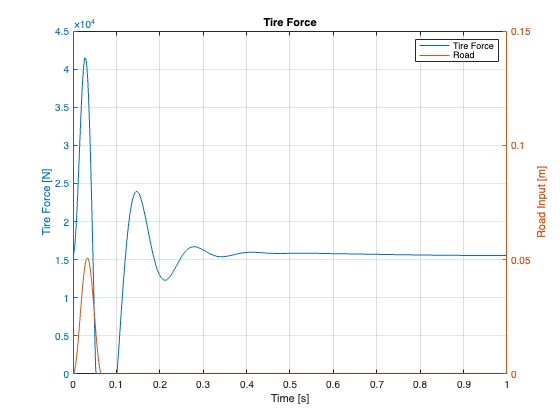


figure(3)
yyaxis left
plot(t,Ft); grid on;
title('Tire Force');
ylabel('Tire Force [N]');
yyaxis right
plot(t,Y);
ylim([0 .15]);
ylabel('Road Input [m]');
xlabel('Time [s]');
legend('Tire Force','Road');

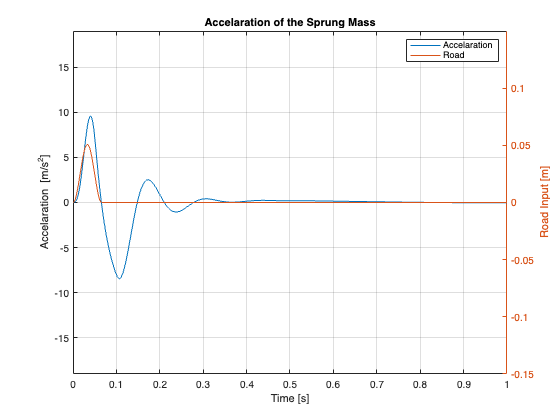


figure(4)
plot(t,dps/ms),grid on
title('Accelaration of the Sprung Mass')
yyaxis left
ylim([-19 19]);
ylabel('Accelaration [m/s^2]')
yyaxis right
plot(t,Y);
ylim([-.15 .15]);
ylabel('Road Input [m]');
xlabel('Time [s]')
legend('Accelaration','Road')

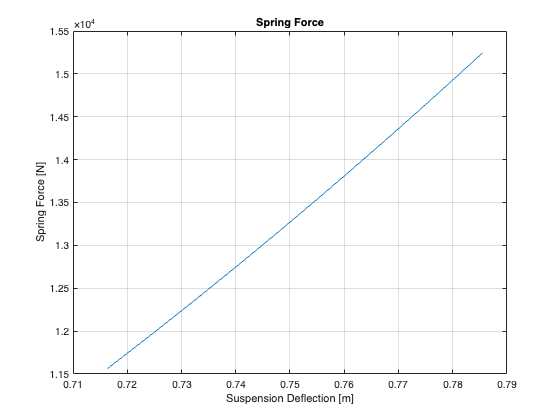

figure(5)
clf
plot(qs,Fss),grid on
title('Spring Force')
xlabel('Suspension Deflection [m]');
ylabel('Spring Force [N]')

Function part

function [ds,ext] = LabDemoFunc(t,s)
global mt ms mus ks bs kt A d u g non_lin G
ps = s(1);
pus = s(2);
qs = s(3);
qt = s(4);

Single bump integration

% single bump
X = u*t;
Y = 1/2*A*(1-cos(2*pi*X/d));
dYdX = 1/2*A*2*pi/d*sin(2*pi*X/d);
if X > d
    Y = 0;
    dYdX = 0;
end
vin = u*dYdX;

No tire force when the tire is off the ground

% tire force that prevents tire pulls down the vehicle
Ft = qt*kt;
if qt <= 0
    Ft = 0;
end

vs = ps/ms; %sprung mass velocity
vus = pus/mus; %unsprung mass velocity

Nonlinear spring switch

if non_lin == 1
    Fs = G*qs^3 + bs*(vus - vs);
    Fss = G*qs^3;
else
    Fs = ks*qs + bs*(vus - vs); % force by spring-damper
    Fss = ks*qs;
end

dps = -ms*g + Fs;
dpus = -mus*g + Ft - Fs;
dqs = vus - vs;
dqus = vin - vus;

ds = [dps; dpus; dqs; dqus];
ext = [X; Y; Ft; vs; vus; vin; Fss];

end